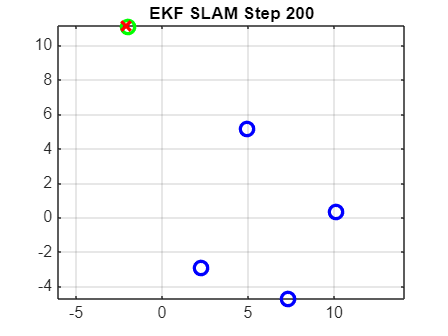

clear; clc; close all;

% Initial state
x_true = [0; 0; 0];       % True robot pose [x; y; theta]
x_est = [0; 0; 0];        % Estimated state (robot + landmarks)
P = eye(3);               % Covariance matrix (starts with robot pose only)

% Noise
R = diag([0.5, 0.5, deg2rad(3)].^2);      % Motion noise
Q = diag([0.1^2, deg2rad(5)^2]);          % Measurement noise [range; bearing]

% Landmarks (ground truth)
true_landmarks = [5 5; 10 0; 7 -5; 2 -3];

% Time setup
dt = 0.1; T = 20; steps = T / dt;

% Logs
x_log = zeros(3, steps);         % True path
x_est_log = zeros(3, steps);     % Estimated path

% Keep track of seen landmarks
observed_landmarks = containers.Map('KeyType','int32','ValueType','int32');

for t = 1:steps
    % Control input
    u = [1; deg2rad(10)];

    % --- True motion ---
    x_true = motion_model(x_true, u, dt);

    % --- EKF Prediction ---
    [x_pred, F] = motion_model(x_est(1:3), u, dt);
    x_est(1:3) = x_pred;
    
    % Extend F for full state
    n = length(x_est);
    F_aug = eye(n);
    F_aug(1:3,1:3) = F;
    P = F_aug * P * F_aug' + blkdiag(R, zeros(n-3));

    % --- Simulate Measurements ---
    [z_all, ids] = simulate_measurements(x_true, true_landmarks, Q);

    for j = 1:length(ids)
        id = ids(j);
        z = z_all(:, j);

        % If new landmark, initialize
        if ~isKey(observed_landmarks, id)
            [x_est, P] = initialize_landmark(x_est, P, z, Q, id);
            observed_landmarks(id) = 1;
        else
            [x_est, P] = ekf_update(x_est, P, z, Q, id);
        end
    end

    % Log states
    x_log(:, t) = x_true;
    x_est_log(:, t) = x_est(1:3);

    % Plot live
    plot_map(x_est, P, x_true, t);
end

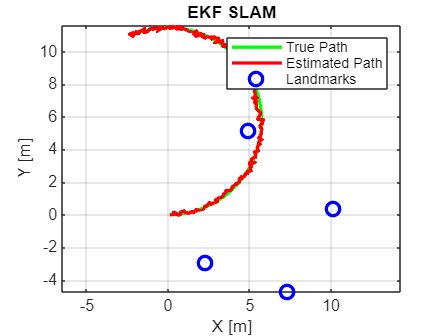


% --- Final Plot ---
figure;
plot(x_log(1, :), x_log(2, :), 'g', 'LineWidth', 2); hold on;
plot(x_est_log(1, :), x_est_log(2, :), 'r', 'LineWidth', 2);
landmarks = reshape(x_est(4:end), 2, [])';
plot(landmarks(:,1), landmarks(:,2), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend('True Path', 'Estimated Path', 'Landmarks');
title('EKF SLAM');
xlabel('X [m]'); ylabel('Y [m]'); axis equal; grid on;